## RF

v = [0, 1;sqrt(3)/2, -1/2;-sqrt(3)/2, -1/2]
ab = [v(:,1)-v(:,2) v(:,1)+v(:,2)]
scatter(ab(:, 2), 0)

ab =    -1.0000    1.0000
    1.3660    0.3660
   -0.3660   -1.3660


yline(0,'Color',"w")
xline(0,'w')
ax = gca;
ax.XGrid = 'on'
axis tight

ax =   Axes with properties:

             XLim: [-1.5000 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


text(ab(:, 2), ab(:, 2)*0-.2,num2str(ab(:,2)), ...
    'Color','w')
plot_darkmode

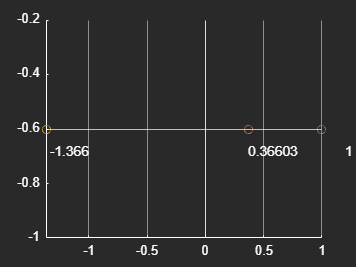

% frequency of operation,

% pulse repetition frequency,
% bandwidth of the system, peak power of the system
[r,u,t,a] = ruta(5.4*10^9, 1e4, 200*10^6, .5*10^6);

v = [2.^(1:7) 128];

ans = 0.0192

log2(v)./v

ans =     0.5000    0.5000    0.3750    0.2500    0.1562    0.0938    0.0547    0.0547


sum(log2(v)./v)%sum(1./v)

ans = 1.9844

Z0 = 100

ZL = 250

ZL = 250

Tm = 0.0480

Tm = .048

f0 = 3.7400

f0 = 3.74

k = 2.1082

k = 2*sqrt(Z0*ZL)/abs(ZL-Z0)

fm = 3.4926

fm = 2*f0*acos(abs(Tm)*k/(sqrt(1-abs(Tm))))/pi

ans = 0.4948

2*(f0-fm)

n = 1/11-105/345

d = 0.9723

d = 1-1/11*105/345

ans = 0.0277

1/11*105/345

ZL = 50

Z0 = 100

Z0 = 100

N = 3

N = 3

Z1 = 91.7004

Z1 = Z0*f(0)

ans =     0.9170    0.7071    0.5946    0.7071


f(0:3)

ans =     0.9170    0.7711    0.7711    0.9170


(ZL./Z0).^(Co(N,0:3)./2^N)

fc = function_handle with value:
    @(n)Co(N,n)


fc = @(n) Co(N,n)

ans =      1     3     3     1


fc(0:3)

ans =     0.1250    0.3750    0.3750    0.1250


(Co(N,0:3)./2^N)

ZL = 12.5

ZL = 12.5000

Z0 = 50

Z0 = 50

N = 4

N = 4

f = @(n) (ZL./Z0).^(Co(N,n)./2^N)

f = function_handle with value:
    @(n)(ZL./Z0).^(Co(N,n)./2^N)


Z1 = Z0*f(0)

Z1 = 45.8502

Z2 = Z1*f(1)

Z2 = 32.4210

Z3 = Z2*f(2)

Z3 = 19.2776

Z4 = Z3*f(3)

Z4 = 13.6313

k = (ZL-Z0)/((ZL+Z0)*2^N)

k = -0.0375

Co(N,0)

ans = 1

f(0:3)

ans =     0.9170    0.7071    0.5946    0.7071


% w = @(f) 2*pi*f
% B = @(XL,RL,Z0) XL + sqrt(RL*((RL^2 + XL^2...
% )/Z0 ...
%     - RL))/(RL^2 + XL^2)*[1 -1]
% Q = @(RL,Z0) sqrt(RL/Z0-1)
% L = RL/(Q0*w(f))
% RL/Q0
% Q0/RL

%% Book
XL = -100

XL = -100

RL = 200

RL = 200

Z0 = 100

Z0 = 100

f = 500

f = 500

w0 = w(f)

w0 = 3.1416e+03

B0 = B(XL,RL,Z0)

B0 =   -99.9951 -100.0049


2*B0/w0

ans =    -0.0637   -0.0637


1./(B0*w0)

ans = 1.0e-05 *

   -0.3183   -0.3183


B0/w0

ans =    -0.0318   -0.0318


Q0 = Q(RL,Z0)

Q0 = 1

% T2
XL = 0

Q = function_handle with value:
    @(RL,Z0)sqrt(RL/Z0-1)


L = 0.2400

ans = 3.5444

ans = 0.2821

XL = -100

RL = 200

Z0 = 100

f = 500

w0 = 3.1416e+03

B0 =   -99.9951 -100.0049


ans =    -0.0637   -0.0637


ans = 1.0e-05 *

   -0.3183   -0.3183


ans =    -0.0318   -0.0318


Q0 = 1

ans = 1.0e-05 *

   -0.3183   -0.3183


XL = 0

RL = 50

Z0 = 0.2500

f = 2.3500

B = function_handle with value:
    @(XL,RL,Z0)XL+sqrt(RL*((RL^2+XL^2)/Z0-RL))/(RL^2+XL^2)*[1,-1]


Q0 = 14.1067

B0 =     0.2821   -0.2821


ans =     0.0191   -0.0191


ans =     0.2400   -0.2400


ans =     3.5444   -3.5444


f = 2.3500

w = function_handle with value:
    @(f)2*pi*f


ans =     0.0382   -0.0382


ans = 0

XL = 0

$$B = \left(\begin{array}{cc} \frac{\sqrt{-\mathrm{RL}\,\left(\mathrm{RL}-\frac{{\mathrm{RL}}^{2}}{Z_{0}}\right)}}{{\mathrm{RL}}^{2}} & -\frac{\sqrt{-\mathrm{RL}\,\left(\mathrm{RL}-\frac{{\mathrm{RL}}^{2}}{Z_{0}}\right)}}{{\mathrm{RL}}^{2}} \end{array}\right)$$

$$ZL = \mathrm{RL}+\mathrm{XL}\,\mathrm{i}$$

$$Zpl = \frac{C\,\left(\mathrm{RL}+\mathrm{XL}\,\mathrm{i}\right)}{C+\mathrm{RL}+\mathrm{XL}\,\mathrm{i}}$$

$$Zin = L+\frac{C\,\left(\mathrm{RL}+\mathrm{XL}\,\mathrm{i}\right)}{C+\mathrm{RL}+\mathrm{XL}\,\mathrm{i}}$$

$$ans = \mathrm{real}\left(\frac{C\,\left(\mathrm{RL}+\mathrm{XL}\,\mathrm{i}\right)}{C+\mathrm{RL}+\mathrm{XL}\,\mathrm{i}}\right)+\mathrm{real}\left(L\right)$$

ans = 0.6667

RL = 50
Z0 = .25
f = 2.35

Q0 = Q(RL,Z0)
B0 = B(XL,RL,Z0)
B0/w(f)
1./(B0*w(f))

1./B0

2*B0/w(f)

sqrt(RL*((RL^2 + XL^2)/Z0 ...
    - RL))/(RL^2 + XL^2)

syms RL Z0
XL = 0
B = XL + sqrt(RL*((RL^2 + XL^2)/Z0 ...
    - RL))/(RL^2 + XL^2)*[1 -1]

syms  L C RL XL Z0

ZL = RL + sqrt(-1)*XL

Zpl = Zp(ZL, C)

Zin = Zpl + L

real(Zin)

Zp = @(Z1, Z2) Z1*Z2/(Z1+Z2)

Zp(1,2)

eqn = a*x^2 + b*x + c == 0

function [combination] = Co(n,k)
%Combination
%   n= total # of elements, k= # of elements chosen
x = factorial(n);
y = factorial(k);
z = factorial(n-k);
combination = x./(y.*z);
end

function [r,u,t,a] = ruta(fo,f,b,p)
c = 3*10^8; r = c/2/b;
u = c/2/f; t = f*100/b; a = t*p;
disp(['range resolution: ', r, ' m']);
disp(['maximum unambiguous range: ', u, ' m']);
disp(['transmit duty cycle: ', t, ' %']);
disp(['average power in the system: ', a]);
end

function axe()
    axes = gca;
    axes.XAxis.TickLabelInterpreter = 'latex';
    axes.YAxis.TickLabelInterpreter = 'latex';
end